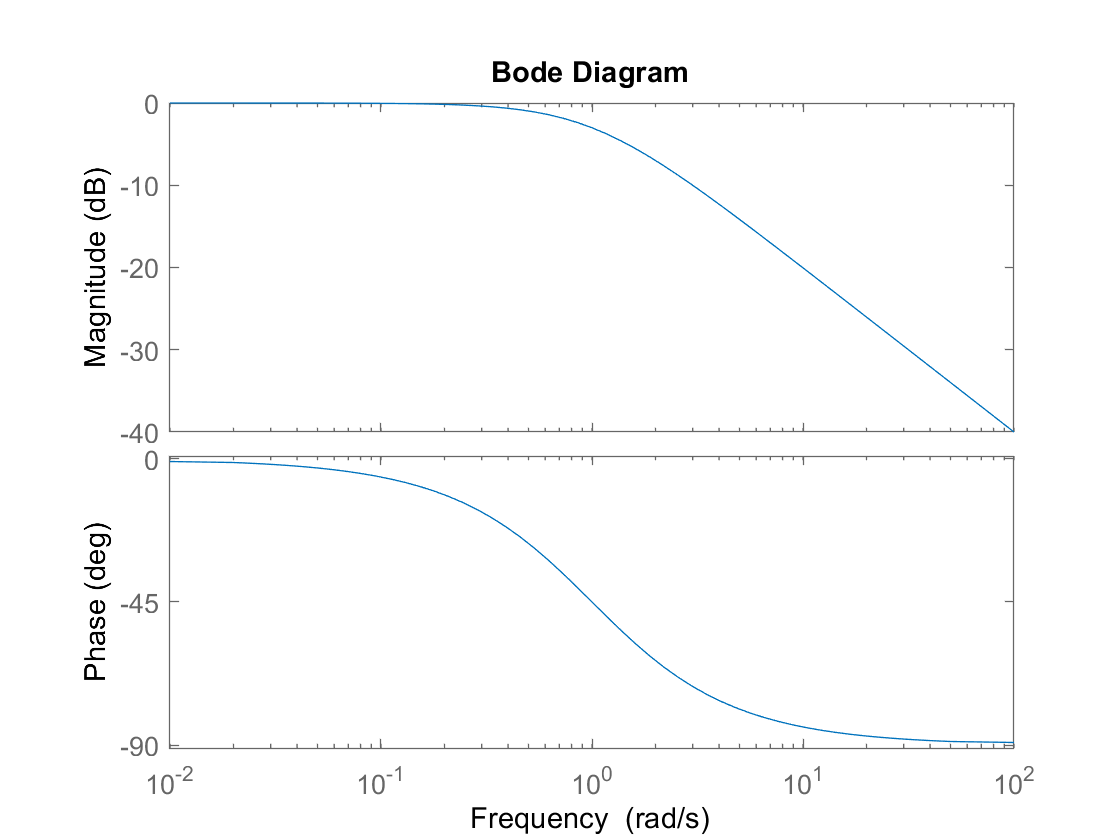

clear; clc; close all;

T = 10;         % simulation final time (seconds)
dt = 0.01;       % time step (seconds)
t = 0:dt:T;    

% Parameters: T(s) = k / (s/w + 1) from single motor model
k = 1;      
omega = 1;

s = tf('s');            
TF = k / (s / omega + 1);   % Transfer function

% step(TF);
bode(TF);

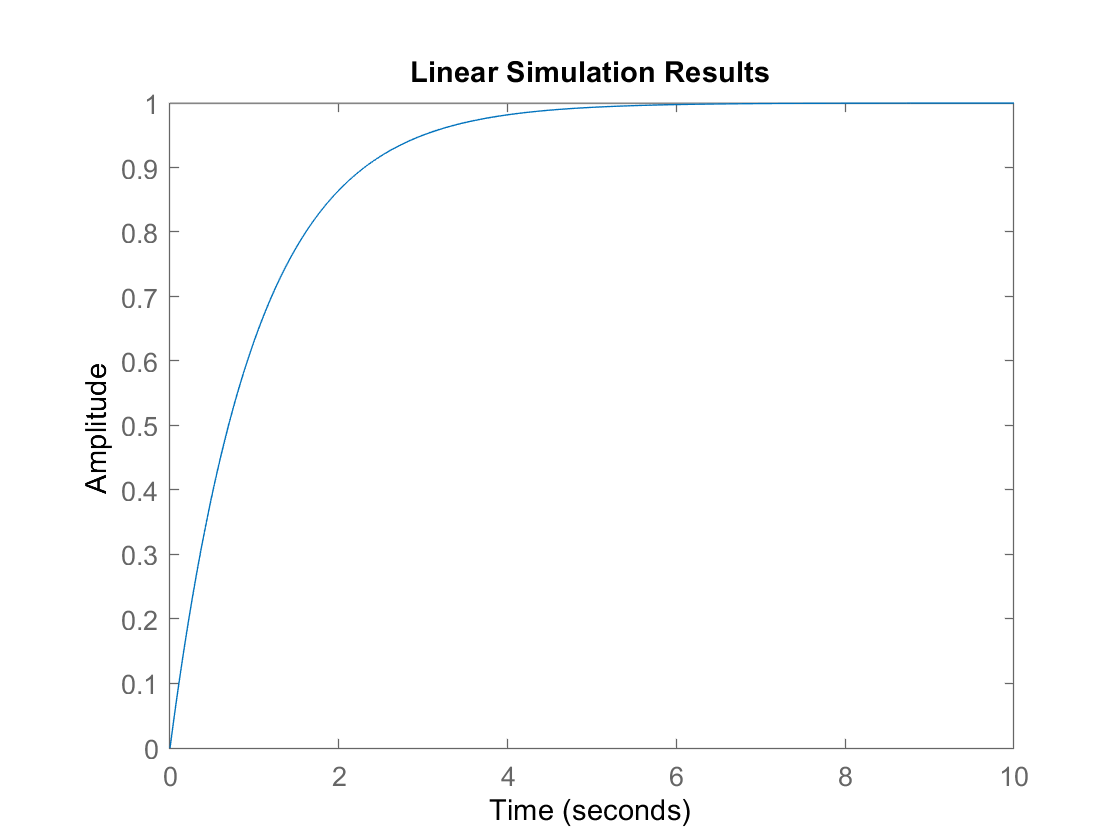

U_step = ones(1, length(t));
lsim(TF, U_step, t);

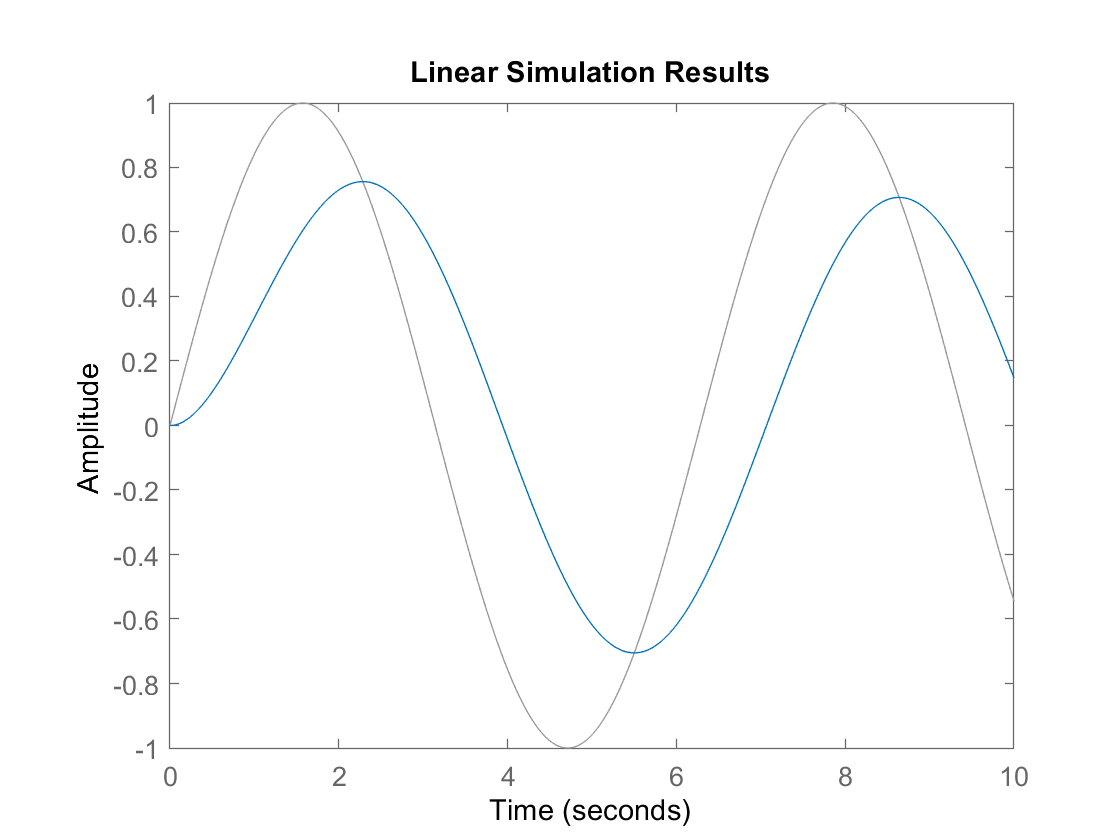

U_sin = sin(omega*t);
lsim(TF, U_sin, t);

Frequencies chosen arbitrarily

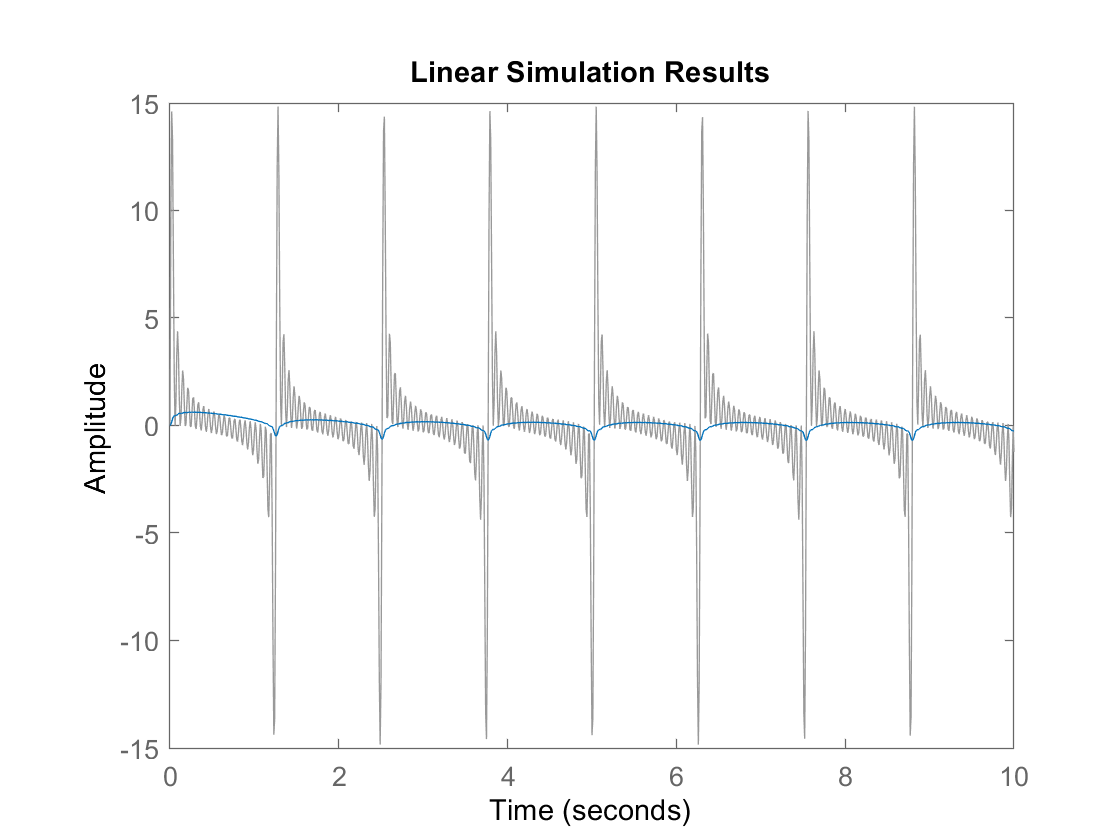

omega_range = 5:5:100;
U_range = zeros(1, length(t));

for i = 1:length(omega_range)
    U_range = U_range + sin(omega_range(i)*t);
end

lsim(TF, U_range, t);

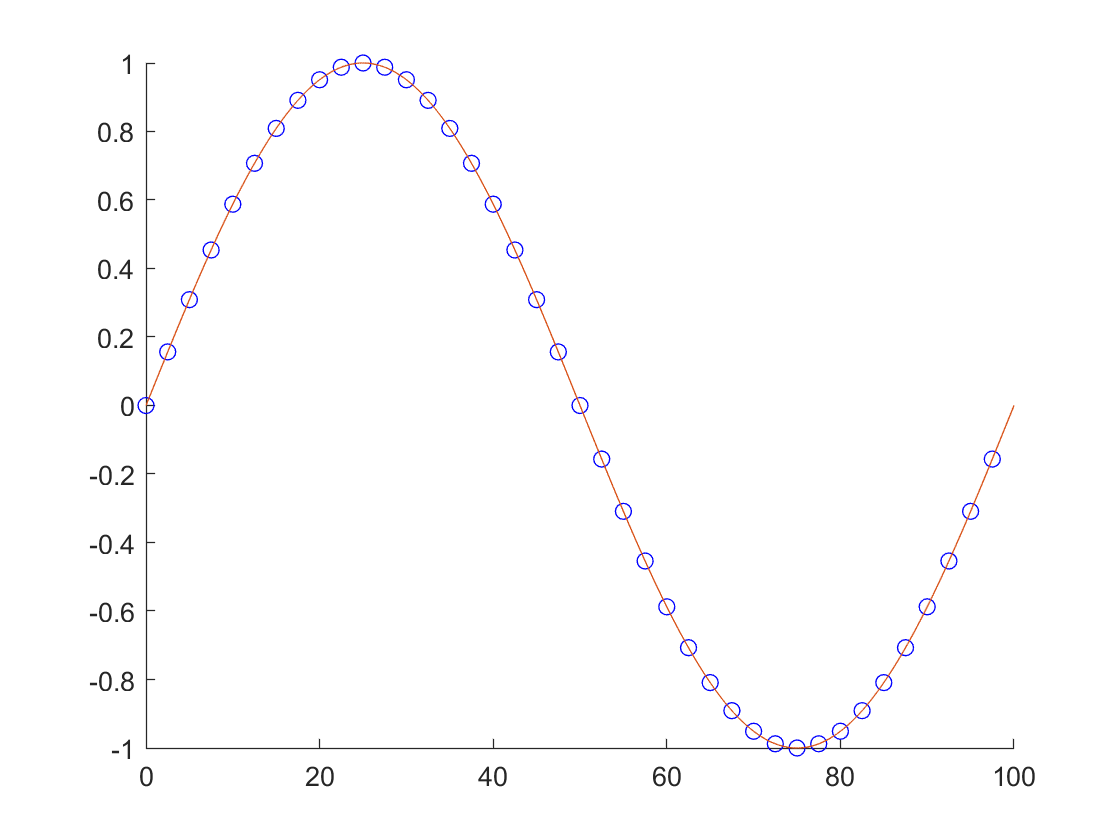

clear; clc; close all;

T = 100;
dt = 0.01;
t = 0:dt:T-dt;      % last value removed to match subsequent signal CHANGE DT TO SEE DIFFERENCES


% Input signal parameters
a = 1;              % amplitude
hertz = 1/T;        % 1/T        
omega = 2*pi*hertz; % signal frequency

t_actual = 0:.01:T;
Y_actual = a*sin(omega*t_actual);

% Sampling parameters
rate = 40;                      % sampling rate
F_sampling = rate*hertz;        % sampling frequency min is 2*omega CHANGE TO SEE DIFFERENCES
T_sampling = 1/F_sampling ;     % sampling period
t_sampling = 0:T_sampling:T-T_sampling;
L = length(t_sampling);         % length of the signal in terms of sampling

% Sampling
Yt = a*sin(omega*t_sampling);   % signal time domain
Ys = fft(Yt);                   % signal frequency domain

P2 = abs(Ys/L);                 % two-sided spectrum
f_2 = F_sampling*(0:L)/L  ;      % frequency domain

P1 = P2(1:L/2 + 1);
P1(2:end - 1) = 2*P1(2:end -1); % one-sided spectrum
f_1 = F_sampling*(0:(L/2))/L;   % frequency domain

hold on
plot(t_sampling, Yt, 'bo')
plot(t_actual, Y_actual)
hold off

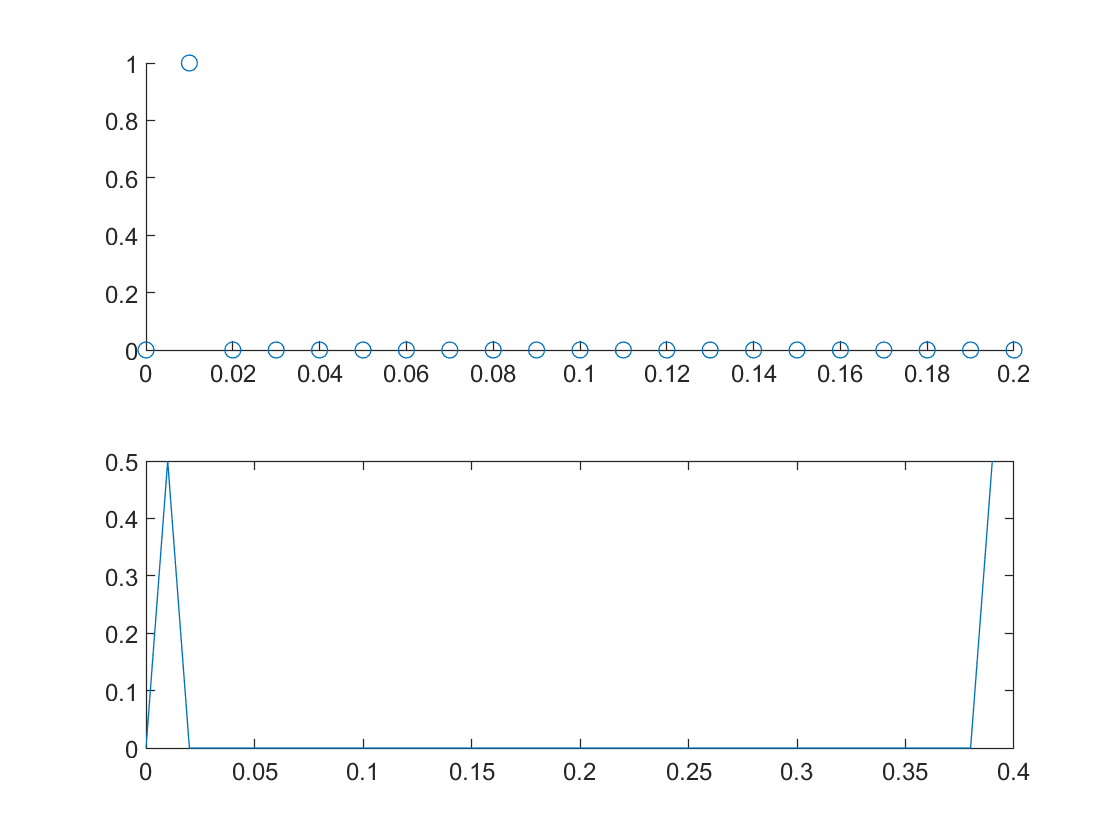


figure

subplot(2,1,1)
scatter(f_1, P1)

subplot(2,1,2)
plot(f_2(1:end-1), P2)

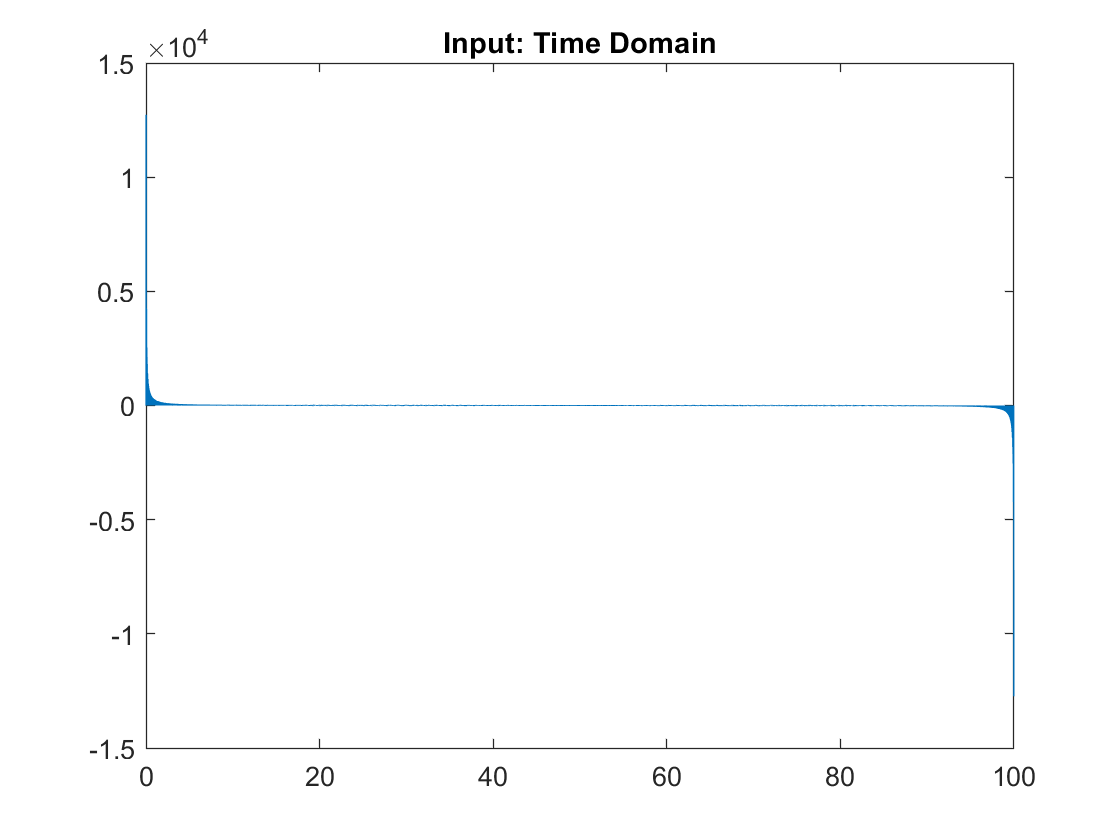

% Sampling parameters
a = 8;
freq_min = 2*pi/T;
freq_nyqist = pi/dt;       
f = 0:freq_min:2*freq_nyqist-freq_min; 
L = T/dt;

tests = 4;   
t2 = 0:dt:T*tests-dt;

omega_range = freq_min:freq_min:freq_nyqist;    % full range of freqs

Ut_range = zeros(1, length(t2));
for i = 1:length(omega_range)/2                % can limit number of freqs to use here
    Ut_range = Ut_range + a*sin(omega_range(i)*t2);
end

Ut_range_cycle = Ut_range(end-length(t)+1:end);
Us_range = abs(fft(Ut_range_cycle)/L);

figure
plot(t, Ut_range_cycle)
title("Input: Time Domain")

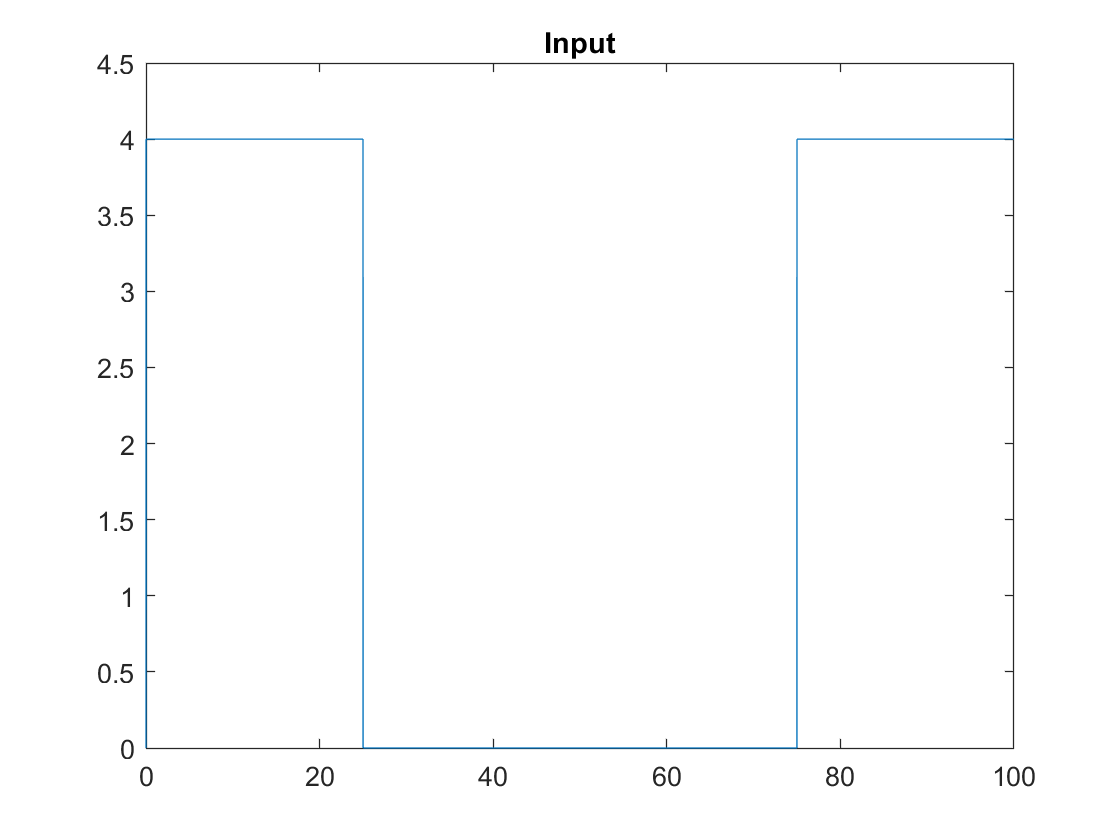


figure
plot(t, Us_range)
title("Input")

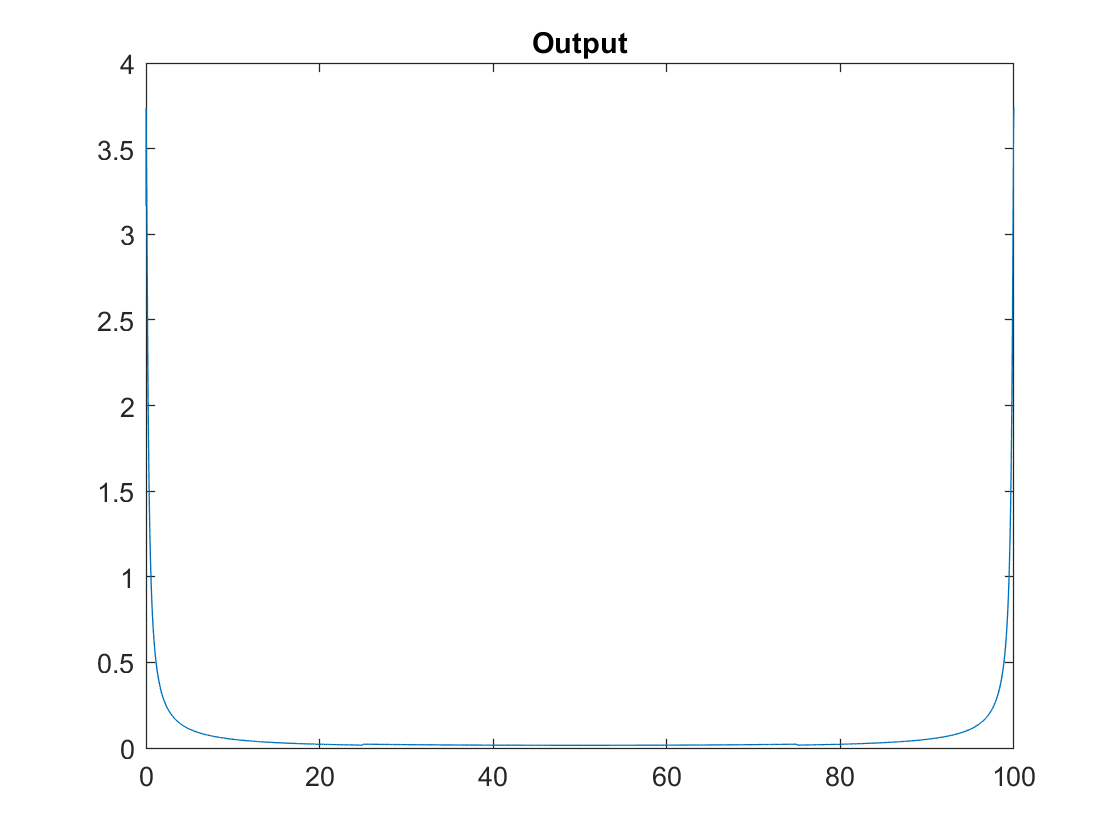



% Parameters: T(s) = k / (s/w + 1) from single motor model
k = 1;    
omega = 1;
s = tf('s');       

TF = k / (s / omega + 1);   % Transfer function

Yt_range = lsim(TF, Ut_range_cycle/2, t);           % divide by two because we only want up to one Nyqist
Ys_range = abs(fft(Yt_range)/length(Yt_range));

figure
plot(t, Ys_range)
title("Output")

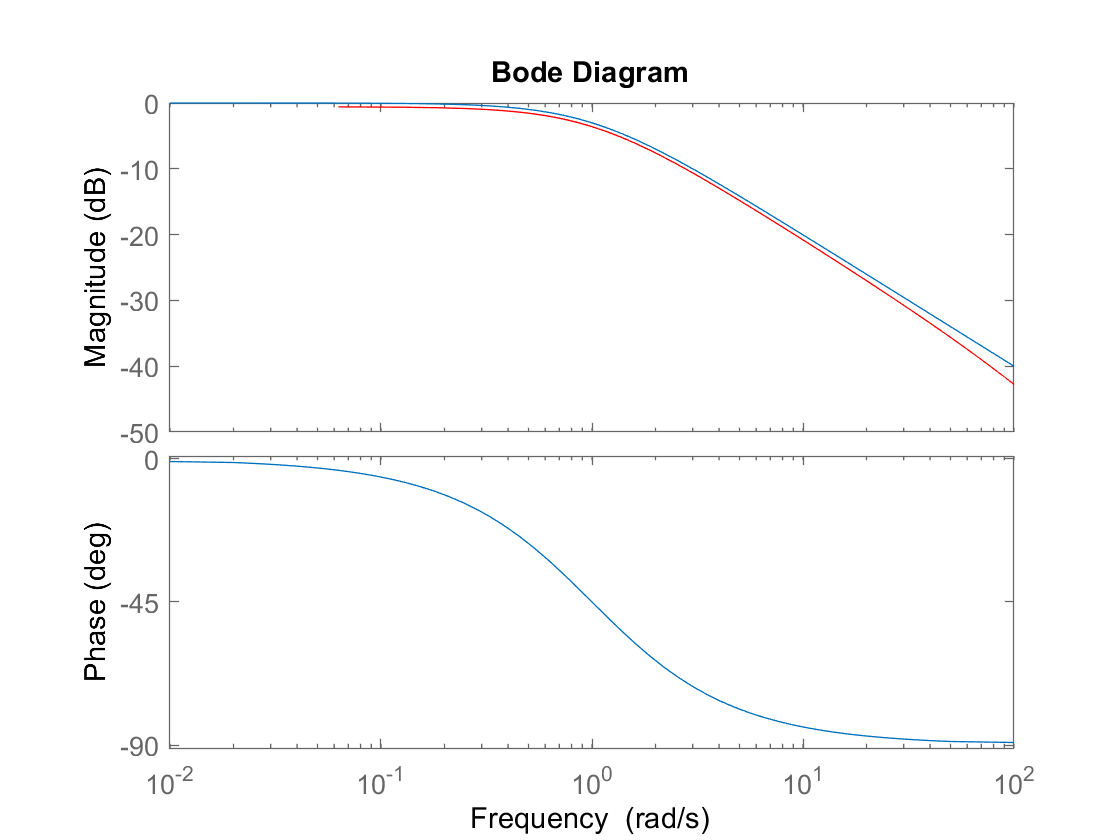


index = find(Us_range >= 1e-3);
Bode_y = Us_range;
Bode_y(index) = Ys_range(index)./Us_range(index)';

figure
semilogx(f(index), 20*log10(Bode_y(index)), 'r')
hold on
bode(TF)